f1 = 17e3;   
f2 = 18e3;
fs = 48e3;      
A=350;
time=960;
sendSignal = zeros(1, time*32);

% 把ip转换为二进制
ipFields = uint8(str2double(split('173.33.45.29', '.')))'

ipFields = 1×4 uint8 行向量
   173    33    45    29


temp=dec2bin(typecast(fliplr(ipFields), 'uint32'))

temp = '10101101001000010010110100011101'

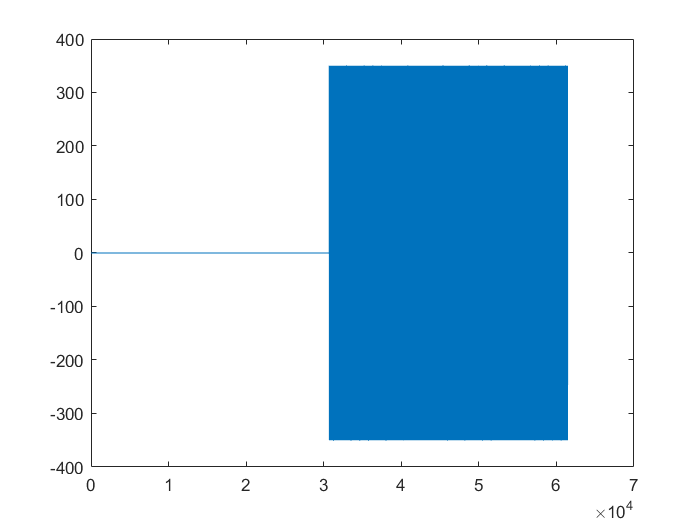

symbal = double(temp)-'0';

% 根据二进制生成正弦波
t = 0:1/fs:(time-1)/fs;
for i=symbal
    if i==0
        temp=A*cos(2*pi*f1*t);
    else
        temp=A*cos(2*pi*f2*t);
    end
    sendSignal = [sendSignal temp];
    
end
plot(sendSignal)

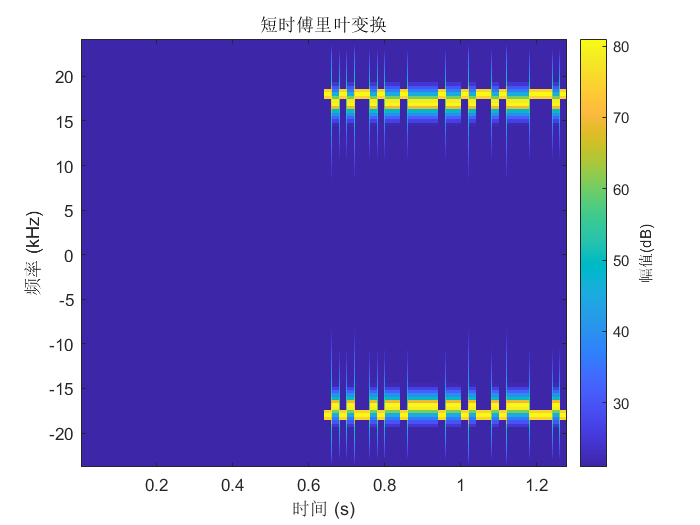

stft(sendSignal, fs)

dlmwrite("send/chirp.txt", sendSignal')




